# Example script showing a generalization of the subspace method for the case when

## the two dichromats do not share exactly a cone fundamental.

The script adds deformation and noise to the cone fundamentals

TG 2023-04-01: This script is stochastic. Run this several times to see the difference. Most of the time the reconstruction is very satisfactory. In other cases it is terrible for some cones. I need to think a bit more where this comes from. Probably because randn gives very big numbers sometimes.

Created By Thomas Goossens  2023

close all;
nbWavelengths=100;
wl_start_nm = 400;


% Helper function to normalize data
n=@(A)A/max(abs(A(:))); % normalize

## Generate LMS cones for three different individuals

We generate three individuals with different LMS cones.

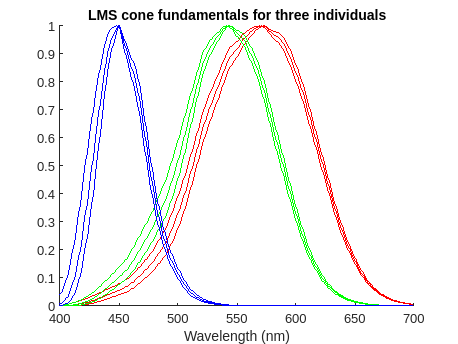

coneParams = DefaultConeParams('cie_asano');
% wl start , stepsize , number of steps
S = [wl_start_nm 1 301];
lambda=SToWls(S);

% Individual 1
coneParams.indDiffParams.dmac=0;
coneParams.indDiffParams.dlens=0;
LMS(:,:,1) = ComputeObserverFundamentals(coneParams,S)';

% Individual 2
coneParams.indDiffParams.dmac=50;
 coneParams.indDiffParams.dlens=50;
LMS(:,:,2) = ComputeObserverFundamentals(coneParams,S)';

% Individual 3
coneParams.indDiffParams.dmac=100;
coneParams.indDiffParams.dlens=100; 
LMS(:,:,3)= ComputeObserverFundamentals(coneParams,S)';

%% Organize L M and S cones in separate matrices.
for i=1:3
    l(:,i)=LMS(:,1,i);
    m(:,i)=LMS(:,2,i);
    s(:,i)=LMS(:,3,i);
end

%% plot the three L, M and S cones
figure;
hold on
plot(lambda,l,'r')
plot(lambda,m,'g')
plot(lambda,s,'b')
title('LMS cone fundamentals for three individuals')
xlabel('Wavelength (nm)')   
exportgraphics(gcf,'fig/cones.pdf')

## Construct the color matching functions for three types of dichromats (leaving out one of the cones)

For each type we leave out one cone fundamental and apply a multiplication with a random 2x2 matrix (we can choose a more relistic one later)

%Protanope (Leave out L)
Cp=rand(2); 
P=[m(:,1) s(:,1)]*Cp;
% Deuteranope   (leave out M)
Cd=rand(2);
D=[l(:,2) s(:,2)]*Cd;
% Tritanope (leave out S)
Ct=rand(2);
T=[l(:,3) m(:,3)]*Ct;

noiselevel =0* 3e-3

noiselevel = 0

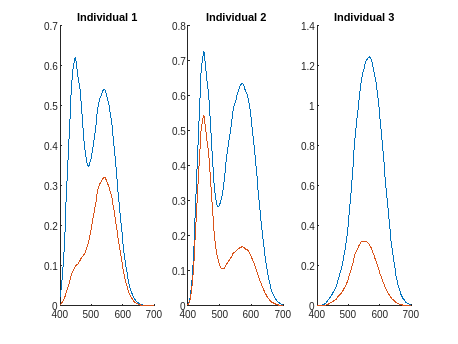

P = P + noiselevel*randn(size(P));
D = D + noiselevel*randn(size(D));
T = T + noiselevel*randn(size(T));
figure;
title('Colormatching functions for each dichromat')
subplot(131)
hold on;plot(lambda,P)
title('Individual 1')
subplot(132)
title('Individual 2')
hold on;plot(lambda,D)
subplot(133)
title('Individual 3')
hold on;plot(lambda,T)

## The null space is null: there is no intersection between the subspaces

This is because the individuals do not actually share a cone fundamental exactly. We can use the SVD to approximate it.

nullspace=null([P D]) % is empty


nullspace =

  4×0 empty double matrix



## Estimate L cone fundamentals

[U,S,V] = svd([D T]);
V4=V(:,4)

V4 =    -0.5760
    0.7527
    0.2434
   -0.2060


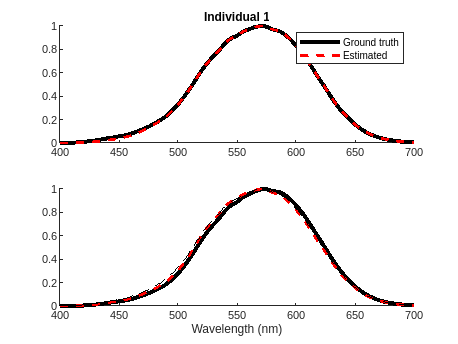

% We can formulate an estimate in both subspaces(column spaces) 
L_estimate_1 = D*V4(1:2); %individual 1
L_estimate_2 = T*V4(3:4); %individual 2

figure; hold on;
subplot(211); hold on
plot(lambda,l(:,2),'k-','linewidth',3)
plot(lambda,abs(L_estimate_1)/max(abs(L_estimate_1)),'r--','linewidth',2)
legend('Ground truth','Estimated')
title('Individual 1')

subplot(212); hold on
plot(lambda,l(:,3),'k-','linewidth',3)
plot(lambda,abs(L_estimate_2)/max(abs(L_estimate_2)),'r--','linewidth',2)
plot(lambda,l(:,2),'k--')
xlabel('Wavelength (nm)')

## Estimate M cone fundamentals

[U,S,V] = svd([P T]);
V4=V(:,4)

V4 =    -0.0776
    0.5604
    0.1052
   -0.8178


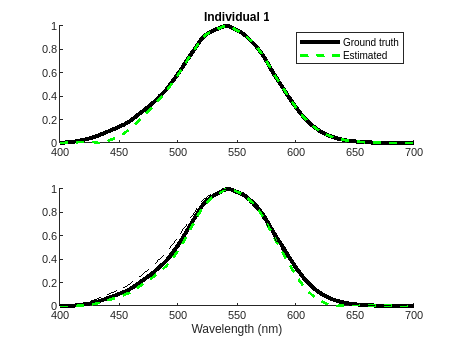

% We can formulate an estimate in both subspaces(column spaces) 
M_estimate_1 = P*V4(1:2); %individual 1
M_estimate_2 = T*V4(3:4); %individual 2

figure; hold on;
subplot(211); hold on
plot(lambda,m(:,1),'k-','linewidth',3)
plot(lambda,abs(M_estimate_1)/max(abs(M_estimate_1)),'g--','linewidth',2)
legend('Ground truth','Estimated')
title('Individual 1')

subplot(212); hold on
plot(lambda,m(:,2),'k-','linewidth',3)
plot(lambda,abs(M_estimate_2)/max(abs(M_estimate_2)),'g--','linewidth',2)
plot(lambda,m(:,1),'k--')
xlabel('Wavelength (nm)')

## Estimate S cone fundamentals

[U,S,V] = svd([P D]);
V4=V(:,4)

V4 =    -0.4121
    0.6980
   -0.1548
    0.5648


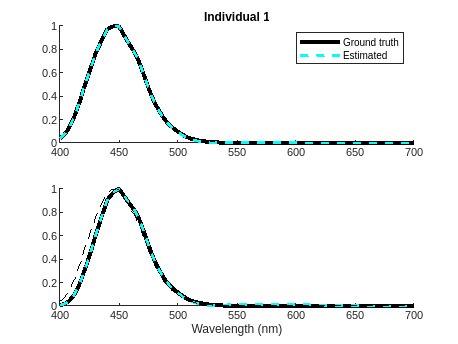

% We can formulate an estimate in both subspaces(column spaces) 
S_estimate_1 = P*V4(1:2); %individual 1
S_estimate_2 = D*V4(3:4); %individual 2

figure; hold on;
subplot(211); hold on
plot(lambda,s(:,1),'k-','linewidth',3)
plot(lambda,abs(S_estimate_1)/max(abs(S_estimate_1)),'c--','linewidth',2)
legend('Ground truth','Estimated')
title('Individual 1')

subplot(212); hold on
plot(lambda,s(:,2),'k-','linewidth',3)
plot(lambda,abs(S_estimate_2)/max(abs(S_estimate_2)),'c--','linewidth',2)
plot(lambda,s(:,1),'k--')
xlabel('Wavelength (nm)')   

## One plot

[U,S,V] = svd([P D]);
V4=V(:,4)

V4 =    -0.4121
    0.6980
   -0.1548
    0.5648


% We can formulate an estimate in both subspaces(column spaces) 
S_estimate_1 = P*V4(1:2); %individual 1
S_estimate_2 = D*V4(3:4); %individual 2

figure; hold on;
S

S =    10.4065         0         0         0
         0    1.9444         0         0
         0         0    1.7339         0
         0         0         0    0.1653
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


href=plot(lambda,l(:,2),'k:','linewidth',2)

href =   Line with properties:

              Color: [0 0 0]
          LineStyle: ':'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [400 401 402 403 404 405 406 407 408 409 410 411 412 413 414 415 416 417 418 419 420 421 422 423 424 425 426 427 428 429 430 431 432 433 434 435 436 437 438 439 440 441 442 443 444 445 446 447 448 449 450 451 452 453 454 455 456 … ]
              YData: [3.4797e-04 4.3670e-04 5.4657e-04 6.8306e-04 8.5343e-04 0.0011 0.0013 0.0016 0.0019 0.0023 0.0028 0.0032 0.0037 0.0043 0.0050 0.0058 0.0064 0.0072 0.0081 0.0091 0.0103 0.0111 0.0121 0.0131 0.0143 0.0155 0.0167 0.0179 0.0193 … ]

  Show all properties

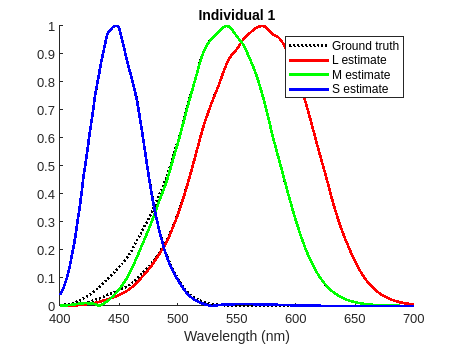

plot(lambda,m(:,1),'k:','linewidth',2);
plot(lambda,s(:,1),'k:','linewidth',2);
hL=plot(lambda,abs(L_estimate_1)/max(abs(L_estimate_1)),'r-','linewidth',2);
hM=plot(lambda,abs(M_estimate_1)/max(abs(M_estimate_1)),'g-','linewidth',2);
hS=plot(lambda,abs(S_estimate_1)/max(abs(S_estimate_1)),'b-','linewidth',2);

legh=legend([href, hL hM hS],'Ground truth','L estimate','M estimate','S estimate');
title('Individual 1')
xlabel('Wavelength (nm)')

exportgraphics(gcf,'fig/individual1.pdf')


figure; hold on;

href=plot(lambda,l(:,3),'k:','linewidth',2);
plot(lambda,m(:,2),'k:','linewidth',2);
plot(lambda,s(:,2),'k:','linewidth',2);
hL=plot(lambda,abs(L_estimate_2)/max(abs(L_estimate_2)),'r-','linewidth',2);
hM=plot(lambda,abs(M_estimate_2)/max(abs(M_estimate_2)),'g-','linewidth',2);
hS=plot(lambda,abs(S_estimate_2)/max(abs(S_estimate_2)),'b-','linewidth',2);

title('Individual 2')
xlabel('Wavelength (nm)')
legh=legend([href, hL hM hS],'Ground truth','L estimate','M estimate','S estimate')

legh =   Legend (Ground truth, L estimate, M estimate, S estimate) with properties:

         String: {'Ground truth'  'L estimate'  'M estimate'  'S estimate'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.6756 0.7544 0.2107 0.1464]
          Units: 'normalized'

  Show all properties


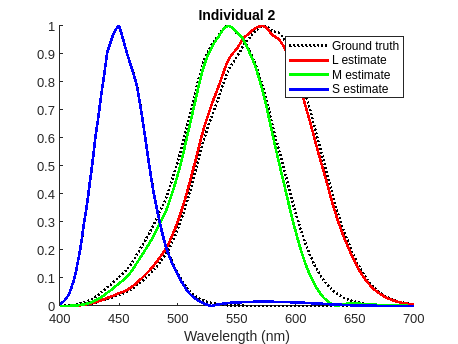

exportgraphics(gcf,'fig/individual2.pdf')